# Example: Reflection and Transmission Coefficients

For a plane wave incident at an oblique angle on a multi-layered structure, the reflection and transmission coefficients determine the amplitude of the wave that is reflected and transmitted at each interface of the multi-layered structure. Knowing the reflection and transmission coefficients is useful for a number of applications. For example, selecting the appropriate launch angle when coupling energy into particular modes in a wave-guide, or determining the thickness and material properties of matching layers for ultrasonic transducers [1,2].

The angles of reflection and transmission at the interfaces between multi-layered media can be found by studying the slowness profiles. However, slowness profiles do not take into account the boundary conditions at the interfaces. Consequently, the magnitude of each of the reflected and transmitted waves cannot be calculated directly using the slowness profiles. For a plane wave incident on a multi-layered structure, the magnitude of the reflection and transmission coefficients are found by normalizing the partial-wave amplitudes by the incident plane wave amplitude. This is automatically calculated when using the .calculate method. This example compares the reflection and transmission coefficients from the model with that from the analytical expressions given in [1] and [2].

[1] Rose, Joseph L. Ultrasonic guided waves in solid media., Cambridge university press, 2014. 

[2] Cheeke, J. David N. Fundamentals and applications of ultrasonic waves. CRC press, 2016.

## Comparing `ElasticMatrix` vs Rose

An example of the reflection and transmission coefficients for a PVDF-Aluminium interface is given below. For a plane compressional wave incident on a PVDF-Aluminium interface, there are four resulting reflected and transmitted waves. These are a reflected $R$ and transmitted $T$ compressional $L$ and shear $S$ wave. The reflection and transmission coefficients have been compared to the analytical solutions for a two-layered elastic-medium from [1] and have an average error less than $1e^{-15}$ which is within numerical precision for a 64 bit floating point number.

## Initialize an `ElasticMatrix` Object

% Define the medium:
my_medium = Medium('PVDF2', Inf, 'aluminium2', Inf);

% Initialize ElasticMatrix class:
my_model = ElasticMatrix(my_medium);

## Setting Parameters

Here only the angle-dependent coefficients are calculated. 

% Set a range of angles:
angle_range = linspace(0.1, 89, 500);   % [degree]
my_model.setAngle(angle_range);

% Set an arbitrary frequency:
my_model.setFrequency(1e6);             % [Hz]

## Calculating Reflection and Transmission Coefficients

The reflection and transmission coefficients are calculated when the `.calculate` method is used.

% Calculate reflection and transmission coefficients:
my_model.calculate;

... calculating matrix method ... 
... frequency-angle calculation ...
... finished calculating matrix method ... 


% Calculate reflection and transmission coefficient using the analytical
% functions from [1] and [2]:
[RL, RS, TL, TS] = calculateReflectionTransmissionAnalytic(...
    angle_range, my_medium);

... calculating reflection and transmission coefficients ...


## Plotting Reflection and Transmission Coefficients

The reflection and transmission coefficients can be plotted using the `.plotRTCoefficients` method. Here, the analytical expressions have also been plotted:

% Plot the reflection coefficients:
my_model.plotRTCoefficients;

... plotting reflection and transmission coefficients ...


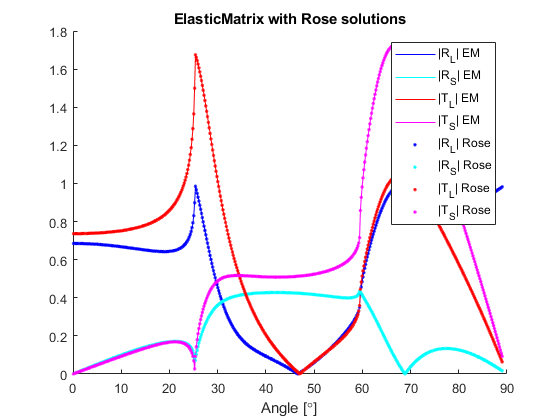

% Add the analytic results:
title('ElasticMatrix with Rose solutions')
hold on
plot(angle_range, abs(RL), 'b.')
plot(angle_range, abs(RS), 'c.')
plot(angle_range, abs(TL), 'r.')
plot(angle_range, abs(TS), 'm.')
hold off
legend('|R_L| EM','|R_S| EM','|T_L| EM','|T_S| EM','|R_L| Rose','|R_S| Rose','|T_L| Rose','|T_S| Rose')

Use` .getPartialWaveAmplitudes` to get the partial-wave amplitudes for a specific layer. Here the wave amplitudes for the first and last layer are needed. Type `help getPartialWaveAmplitudes` for more details.

pwa_layer_1 = my_model.getPartialWaveAmplitudes(1);
pwa_layer_2 = my_model.getPartialWaveAmplitudes(2);

% Calculate normalized errors:
error_RL = (abs(RL) - abs(pwa_layer_1.qL_up(1, :))) ./ abs(RL);
error_RS = (abs(RS) - abs(pwa_layer_1.qS_up(1, :))) ./ abs(RS);
error_TL = (abs(TL) - abs(pwa_layer_2.qL_dw(1, :))) ./ abs(TL);
error_TS = (abs(TS) - abs(pwa_layer_2.qS_dw(1, :))) ./ abs(TS);

% Print Errors
disp('Mean errors for solid-solid medium')

Mean errors for solid-solid medium


disp(['Mean error RL : ', num2str(mean(error_RL))])

Mean error RL : -3.5063e-16


disp(['Mean error RL : ', num2str(mean(error_RS))])

Mean error RL : 6.5532e-15


disp(['Mean error TL : ', num2str(mean(error_TL))])

Mean error TL : 1.1419e-15


disp(['Mean error TS : ', num2str(mean(error_TS))])

Mean error TS : 6.823e-16


## Comparing `ElasticMatrix` vs Cheeke

An example of the reflection and transmission coefficients for a water-Aluminium interface is given below. For a plane compressional wave incident on a water-Aluminium interface, there are three resulting reflected and transmitted waves. These are a reflected $R$ and transmitted $T$ compressional $L$ and wave and a transmitted shear $S$ wave. The reflection and transmission coefficients have been compared to the analytical solutions for a two-layered elastic-medium from [2].

## Initialize an `ElasticMatrix` Object

% Define the medium:
my_medium = Medium('water', Inf, 'aluminium2', Inf);

% Initialize ElasticMatrix class:
my_model = ElasticMatrix(my_medium);

## Setting Calculation Parameters

% Define an angle range:
angle_range = linspace(0.1, 89, 500);

% Set parameters:
my_model.setAngle(angle_range);

% Set an arbitrary frequency:
my_model.setFrequency(1e6);

## Calculating Reflection and Transmission Coefficients

The reflection and transmission coefficients are calculated when the `.calculate` method is used.

% Calculate reflection and transmission coefficients:
my_model.calculate;

... calculating matrix method ... 
... frequency-angle calculation ...
... finished calculating matrix method ... 


% Calculate reflection and transmission coefficient using the analytical
% functions from [1] and [2]:
[RL, ~, TL, TS] = calculateReflectionTransmissionAnalytic(...
    angle_range, my_medium);

... calculating reflection and transmission coefficients ...


## Plotting Reflection and Transmission Coefficients

The reflection and transmission coefficients can be plotted using the `.plotRTCoefficients` method. Here, the analytical expressions have also been plotted:

% Plot the reflection coefficients:
my_model.plotRTCoefficients;

... plotting reflection and transmission coefficients ...


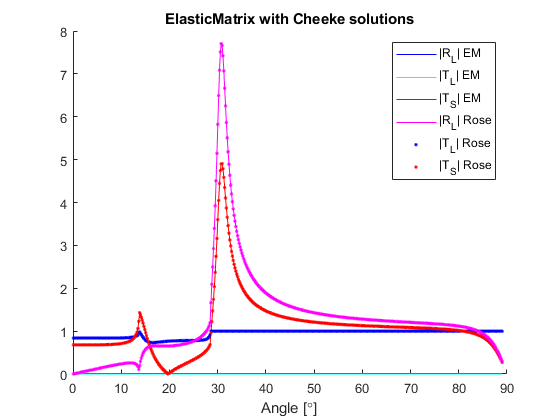

% Add the analytic results:
title('ElasticMatrix with Cheeke solutions')
hold on
plot(angle_range, abs(RL), 'b.')
plot(angle_range, abs(TL), 'r.')
plot(angle_range, abs(TS), 'm.')
hold off
legend('|R_L| EM','|T_L| EM','|T_S| EM','|R_L| Rose','|T_L| Rose','|T_S| Rose')

Use `.getPartialWaveAmplitudes` to get the partial-wave amplitudes for a specific layer. Here the wave amplitudes for the first and last layer are needed. Type `help getPartialWaveAmplitudes` for more details.

pwa_layer_1 = my_model.getPartialWaveAmplitudes(1);
pwa_layer_2 = my_model.getPartialWaveAmplitudes(2);

% Calculate normalized errors:
error_RL = (abs(RL) - abs(pwa_layer_1.qL_up(1, :))) ./ abs(RL);
error_TL = (abs(TL) - abs(pwa_layer_2.qL_dw(1, :))) ./ abs(TL);
error_TS = (abs(TS) - abs(pwa_layer_2.qS_dw(1, :))) ./ abs(TS);

Note: the errors for the case of a fluid first layer are larger as the partial wave method approximates the fluid layer as having a very low shear speed.

% Print errors:
disp('Mean errors for fluid-solid medium - no reflected shear')

Mean errors for fluid-solid medium - no reflected shear


disp(['Mean error RL : ', num2str(mean(error_RL))])

Mean error RL : 6.1451e-06


disp(['Mean error TL : ', num2str(mean(error_TL))])

Mean error TL : 1.4423e-05


disp(['Mean error TS : ', num2str(mean(error_TS))])

Mean error TS : 1.5152e-05
